# 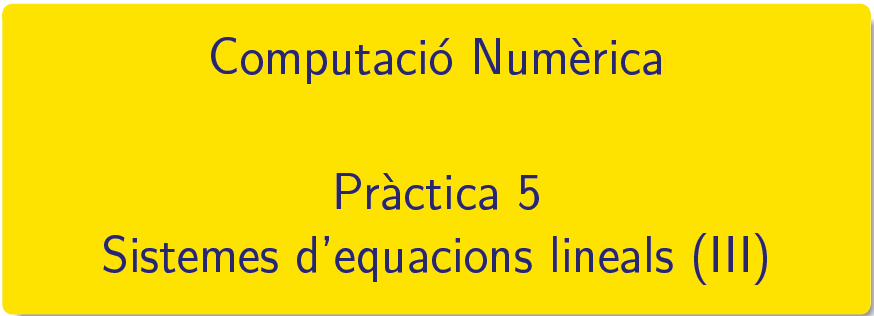

===========================================================================

# Pràctica 5. Mètode de les potències. 

## 1. Valors i vectors propis d'una matriu. Mètode de la potència.

### Part I. Algorismes i jocs de proves

- Escriviu una programa que realitzi $m$ passos del mètode de la potència normalitzat quan aquest s'aplica a una matriu $A$ de $n\times n\,,$ a partir d'un vector inicial $x^{(0)}$. En cada pas, imprimiu el vector $x^{(k)}$ i el quocient $r_k$ en curs. Feu un joc de proves amb diferents matrius. 

- Escriviu una programa que realitzi $m$ passos del mètode de la potència inversa quan aquest s'aplica a una matriu $A$ de $n\times n\,,$ a partir d'un vector inicial $x^{(0)}$. En cada pas, imprimiu el vector $x^{(k)}$ i el quocient $r_k$ en curs. Feu un joc de proves amb diferents matrius.

-  Afegui el criteri del quocient de Rayleigh per a matrius simètriques als vostres scripts del mètode de la potència.  Feu un joc de proves amb diferents matrius.

**Joc de proves**

- Calculeu, amb quatre xifres significatives, el valor propi dominant de la matriu:   $A=\left (\begin{array}{rrr}
1 & 0 & -1 \\
1 & 2 & 1 \\
2 & 2 & 3
\end{array} \right)$  Proveu amb $x^0_{max}=\left (\begin{array}{r} 0 \\ 0\\ 1 \end{array} \right)\,,\quad   x^0_{min}=\left (\begin{array}{r} 1 \\ -1\\ 1 \end{array} \right)\$

A = -[1 0 -1; 1 2 1; 2 2 3]

A =     -1     0     1
    -1    -2    -1
    -2    -2    -3


valors_vap = roots(poly(A))       % mètode teòric: polinomi característic

valors_vap =    -3.0000
   -2.0000
   -1.0000


xk = [0, 0 ,1]';
% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
% veure Mpotencia.html
% veure MPRayleigh.html
k = 0;
m = 0;
val = 1;
while (val >= 0.5e-4 && k < 100)
    z = A*xk;
    %m = norm(z, 'inf'); No podem fer servir aquesta normalització, ja que
    %es carrega el signe del nº.
    [~, j] = max(abs(z)); %j: índex del valor màxim de z (en v.abs)
    m = z(j);
    xk1 = z/m;
    k = k+1;
    xparada = xk1-xk;
    val = norm(xparada, 'inf')/norm(xk1, 'inf');
    xk = xk1;
end
tolerancia = val

tolerancia = 1.6935e-05

iteracions = k

iteracions = 10

VAP = m

VAP = -3

VEP = xk1

VEP =    -0.5000
    0.5000
    1.0000


A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


valors_vap = roots(poly(A))       % mètode teòric: polinomi característic

valors_vap =     3.0000
    2.0000
    1.0000


xk = [1, -1 ,1]';
% quatre xifres significatives --> 0.5e-4 fita de l'error relatiu aproximat
% veure Mpotencia.html
% veure MPRayleigh.html
k = 0;
m = 0;
val = 1;
[L, U, P] = lu(A);
%METODE MIN
while (val >= 0.5e-4 && k < 100)
    z = U\(L\P*xk);
    %m = norm(z, 'inf'); No podem fer servir aquesta normalització, ja que
    %es carrega el signe del nº.
    [~, j] = max(abs(z)); %j: índex del valor màxim de z (en v.abs)
    m = z(j);
    xk1 = z/m;
    k = k+1;
    xparada = xk1-xk;
    val = norm(xparada, 'inf')/norm(xk1, 'inf');
    xk = xk1;
end
tolerancia = val

tolerancia = 2.2581e-05

iteracions = k

iteracions = 10

VAP = 1/m

VAP = 1.0000

VEP = xk1

VEP =     1.0000
   -1.0000
    0.0000


### Part II. Practiquem ...

#### Exercici 1.  Valors propis de mòdul màxim i mínim. 

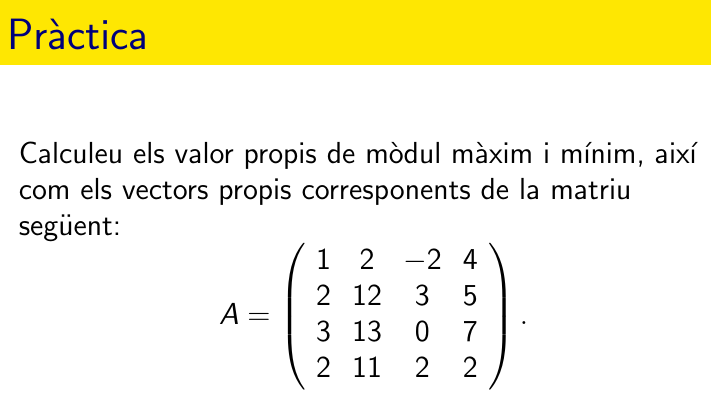

A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
xk = [0, 0 ,1, 0]';
k = 0;
m = 0;
val = 1;
%MÈTODE MAX
while (val >= 0.5e-4 && k < 100)
    z = A*xk;
    %m = norm(z, 'inf'); No podem fer servir aquesta normalització, ja que
    %es carrega el signe del nº.
    [~, j] = max(abs(z)); %j: índex del valor màxim de z (en v.abs)
    m = z(j);
    xk1 = z/m;
    k = k+1;
    xparada = xk1-xk;
    val = norm(xparada, 'inf')/norm(xk1, 'inf');
    xk = xk1;
end
tolerancia = val

tolerancia = 1.6333e-05

iteracions = k

iteracions = 7

VAP = m

VAP = 19.1821

VEP = xk1

VEP =     0.1719
    1.0000
    0.9875
    0.7752


A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
valors_vap = roots(poly(A)) 

valors_vap =    19.1820
   -2.4531
   -1.7411
    0.0122


xk = [1, 0 ,0, 0]';
k = 0;
m = 0;
val = 1;
[L, U, P] = lu(A);
%METODE MIN
while (val >= 0.5e-4 && k < 100)
    z = U\(L\P*xk);
    %m = norm(z, 'inf'); No podem fer servir aquesta normalització, ja que
    %es carrega el signe del nº.
    [~, j] = max(abs(z)); %j: índex del valor màxim de z (en v.abs)
    m = z(j);
    xk1 = z/m;
    k = k+1;
    xparada = xk1-xk;
    val = norm(xparada, 'inf')/norm(xk1, 'inf');
    xk = xk1;
end
tolerancia = val

tolerancia = 1.4720e-05

iteracions = k

iteracions = 3

VAP = 1/m

VAP = 0.0122

VEP = xk1

VEP =     1.0000
   -0.2257
    0.2501
   -0.0090


#### Exercici 2.  Quocient de Rayleigh 

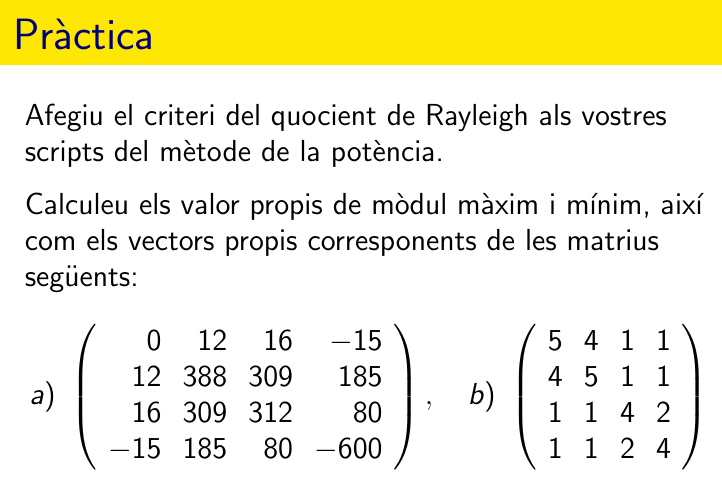

%b)
A = [5 4 1 1;4 5 1 1;1 1 4 2;1 1 2 4]

A =      5     4     1     1
     4     5     1     1
     1     1     4     2
     1     1     2     4


%A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
xk = [0, 0 ,1, 0]';
k = 0;
m = 0;
val = 1;
while (val >= 0.5e-4 && k < 100)
    z = A*xk;
    m = (xk'*z)/(xk'*xk);
    xk1 = z/norm(z);
    k = k+1;
    xparada = xk1-xk;
    val = norm(xparada)/norm(xk1);
    xk = xk1;
end
tolerancia = val

tolerancia = 3.0518e-05

iteracions = k

iteracions = 16

VAP = m

VAP = 10.0000

VEP = xk1

VEP =     0.6324
    0.6324
    0.3162
    0.3162


## 2. Valors i vectors propis d'una matriu. Mètode QR.

### Part I. Algorisme i joc de proves

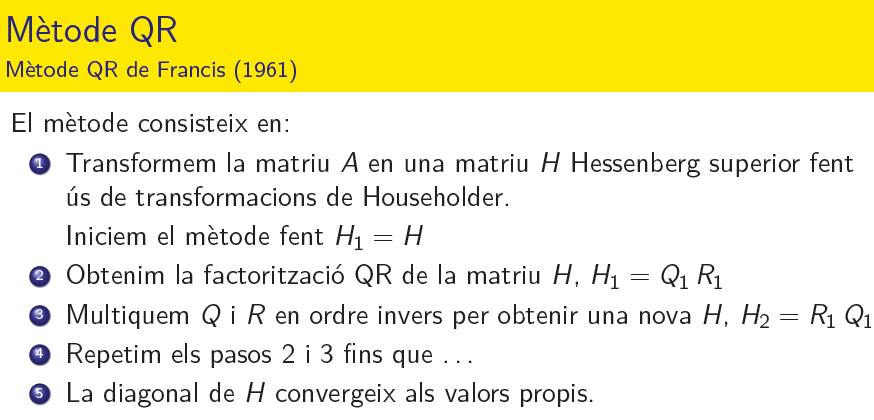

A = [0 12 16 -15;12 388 309 185;16 309 312 80;-15 185 80 -600]

A =      0    12    16   -15
    12   388   309   185
    16   309   312    80
   -15   185    80  -600


Hk = A;
k = 0;
control = 1;
[P, Hk] = hess(Hk);
V = P;
while (k < 500 && control > 5e-5)
    %2:
    [Q, R] = qr(Hk);
    V = V*Q;
    %3:
    Hk = R*Q;
    control = norm(tril(Hk, -1), 1);
    k = k+1;
end
vaps = diag(Hk)

vaps =   690.3367
 -634.6322
   45.0188
   -0.7233


vaps2 = V

vaps2 =     0.0248   -0.0272   -0.1296   -0.9909
    0.7498    0.1699    0.6357   -0.0690
    0.6446    0.0282   -0.7554    0.1141
    0.1472   -0.9847    0.0916    0.0187


V'*A*V

ans =   690.3367    0.0000    0.0000   -0.0000
    0.0000 -634.6322   -0.0000   -0.0000
    0.0000   -0.0000   45.0188   -0.0000
   -0.0000   -0.0000   -0.0000   -0.7233


### Part II. Practiquem ...

#### Exercici 3.  Mètode QR

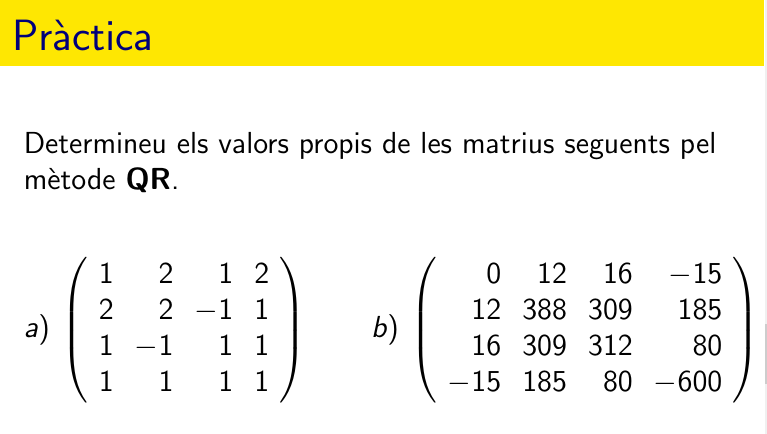

% veure practica5_exercici3.html

## 2.2 Matriu pseudoinversa. Singular Value Decomposition

### Part II. Practiquem ...

Documentació de MATLAB®, [valors singulars](https://es.mathworks.com/help/matlab/math/singular-values.html?searchHighlight=svd&s_tid=srchtitle)

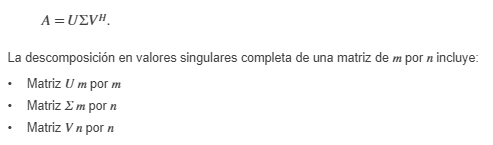

rng('default')
A = randn(6,3)               % matriu qualsevol
[U,S,V] = svd(A)             % U*S*V'-A
control = U*S*V'-A

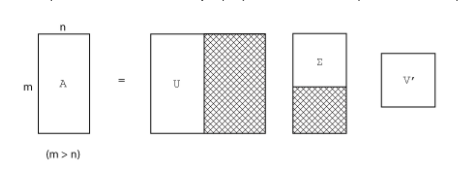

[U,S,V] = svd(A,0)
control =   U*S*V'-A

A =     0.5377   -0.4336    0.7254
    1.8339    0.3426   -0.0631
   -2.2588    3.5784    0.7147
    0.8622    2.7694   -0.2050
    0.3188   -1.3499   -0.1241
   -1.3077    3.0349    1.4897


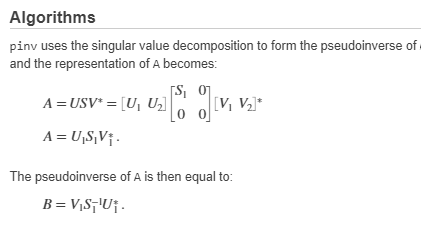

pinversa=pinv(A), B = V*inv(S)*U'

U =    -0.0721    0.0747   -0.6808    0.4983   -0.2036   -0.4857
   -0.0618    0.6554   -0.2259   -0.6432    0.1342   -0.2895
    0.6923   -0.2595    0.2151   -0.0991    0.1551   -0.6109
    0.3526    0.6969    0.2965    0.5244    0.0805    0.1434
   -0.2241   -0.0850   -0.1006    0.1872    0.9463   -0.0433
    0.5806   -0.0677   -0.5840   -0.1346    0.1203    0.5335


S =     6.0992         0         0
         0    2.7539         0
         0         0    1.2867
         0         0         0
         0         0         0
         0         0         0


V =    -0.3677    0.9043   -0.2167
    0.9065    0.4006    0.1337
    0.2077   -0.1473   -0.9670


control_dreta = (B*A)*B, control_esquerra=(A*B)*A

control = 1.0e-14 *

    0.0444   -0.0500   -0.0666
    0.3109    0.1665   -0.0611
   -0.2665    0.3997    0.0777
    0.2220    0.3553   -0.0028
    0.0056   -0.1554   -0.0236
   -0.1998    0.3997    0.0444


#### Exercici 4.  Rutina svd

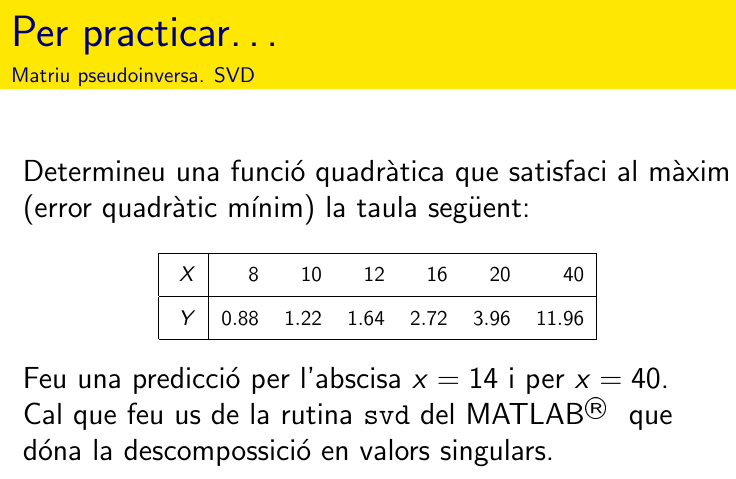

% veure practica5_exercici4


U =    -0.0721    0.0747   -0.6808
   -0.0618    0.6554   -0.2259
    0.6923   -0.2595    0.2151
    0.3526    0.6969    0.2965
   -0.2241   -0.0850   -0.1006
    0.5806   -0.0677   -0.5840


S =     6.0992         0         0
         0    2.7539         0
         0         0    1.2867


V =    -0.3677    0.9043   -0.2167
    0.9065    0.4006    0.1337
    0.2077   -0.1473   -0.9670


#### Exercici 5.  Sistema  sobredeterminat

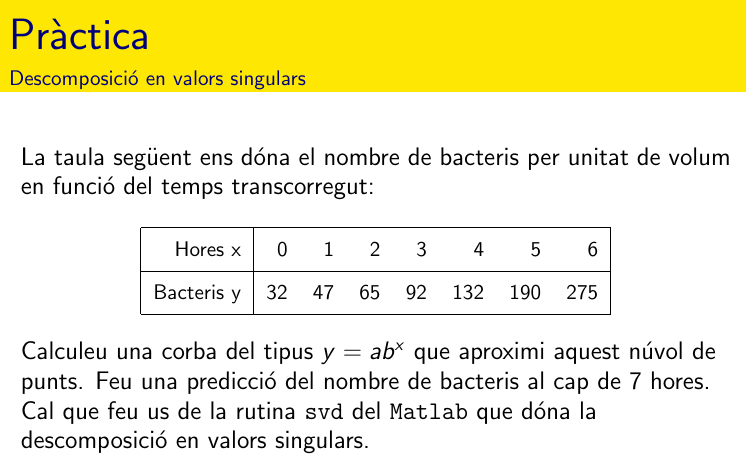

% veure practica5_exercici5

control = 1.0e-14 *

    0.0444   -0.0500   -0.0666
    0.3109    0.1665   -0.0611
   -0.2665    0.3997    0.0777
    0.2220    0.3553   -0.0028
    0.0056   -0.1554   -0.0236
   -0.1998    0.3997    0.0444


pinversa =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


B =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


control_dreta =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


control_esquerra =     0.5377   -0.4336    0.7254
    1.8339    0.3426   -0.0631
   -2.2588    3.5784    0.7147
    0.8622    2.7694   -0.2050
    0.3188   -1.3499   -0.1241
   -1.3077    3.0349    1.4897


`Document preparat per M. Àngela Grau Gotés, 15 de març de 2023`